# Demo of analyse_file.m

This Matlab Live Editor file performs the same calulations as analyse_file.m, but lets the user follow the process step by step.

## Purpose

The output from an optical tweezer moleculte streching experiment is analysed to find any unfolding or refolding events and report the force and position of the optical trap (extent) at transition.  

### Inputs

- **filename: ** Name of the text file with experiment results. A typical name is '04082022/uA.txt'.  This indicates that the file is in a folder named from the experiment date.  filename may also include the full file path, but normally this will be supplied by datafolder.m.

- **plotting: **Logical variable.  If True or 1, a plot of force vs time is created, showing the identified transition points

### Outputs

- **Tu: ** Matlab table with one row for each unfolding event, giving details such as time, force etc.

- **Tr:**  Same as Tu, but for refolding events

- **Optional outputs:** number of stretching and relaxing events, time sereis for force and extent.

### Dependencies

#### Matlab toolbox functions

- findpeaks.m from the Signal Processing Toolbox

#### User functions

analyse_file.m uses the followinng functions:

- analyse_stretch.m

- dominant_frequency.m

- read_experimentfile.m

- datafolder.m

- valid_ranges.m

These functions will normally be distributed along with analyse_file.m

The latter two will need modification to fit the user's setup and data files.

## Preliminaries

### Read experiment file

  filename = '07082022/cA.txt';   % Use any relevant file name for the demo

  [Filename,time0,f0,xx0,T] = read_experiment_file(filename);
  % Regardless of the form of the input filename,  
  % the output Filename has the form 'MMddyyyy/<xx>.txt'

  x0 = mean(xx0,2);  % Mean values of extent measurements

The function read_experiment_file starts reading data from line four in the file, so the values with row number (index) ix in the column arrays time0, f0 and x0 correspond to line ix+4 in the file.  Files sometimes contain sections with widely varing stretching speeds, so they must be analysed separately.  Files may also contain garbage sections that can confuse the identification of stretching/relaxing episodes.  You may specify the index ranges for the relevant parts in the file valid_data_ranges.m:

  r = valid_data_ranges(Filename);
  if isempty(r)
    r = [1,numel(f0)];  % No specified ranges: Use the whole file
  end 
  n_parts = size(r,1);  % Number of parts to be analysed

### Initialise output tables

The table Tu contains one row for each unfolding event. Tr contains one row per refolding. The columns are: 

- Filename

- Time (seconds since start of experiment)

- Deltax (nm) The change in extent from the transistion until the force returns to the value a transition

- Force (pN) The force at transititon

- Forceshift (pN) The difference between the linear force fits at the transition

- Fdot (pN/s) The rate of change of the force before the transition

- Temperature (°C)  Temperature as coded in the Status column in the text file.  

- Lineno (-) Line number in the text file correstponding to the start of the unfolding or refolding trasition

  Tu = cell2table(cell(0,8),'VariableNames',{'Filename','Time','Deltax','Force','Forceshift','Fdot','Temperature','Lineno'});
  Tr = cell2table(cell(0,8),'VariableNames',{'Filename','Time','Deltax','Force','Forceshift','Fdot','Temperature','Lineno'});

### Initialise plot

Plot the force time series in grey color, as background for plotting the valid ranges.

  figure;  
  plot(time0,f0,"Color",.7*[1 1 1]); 

## Analyse parts

  for part = 1:n_parts
    % Define variables for this part
    index_range = r(part,1):r(part,2);
    f = f0(index_range);  % Force
    x = x0(index_range);  % Extent
    time = time0(index_range);

Peaks and valleys in the force time series separate the individual unfolding and refolding streches.  We use a Fourier transform to find the dominant frequency and specify parameters for the findpeaks function.

    %  Find peaks and valleys in the force data
    nu = dominant_frequency((0:length(f)-1),(f-mean(f)));
    peak_distance = 1/nu;
    MinPeakDistance = min(500,fix(peak_distance/2));
    MinPeakWidth = min(200,fix(peak_distance/5));
    
    [hival,hipos] = findpeaks(f,'MinPeakDistance',MinPeakDistance,'MinPeakWidth',MinPeakWidth);
    [loval,lopos] = findpeaks(-f,'MinPeakDistance',MinPeakDistance,'MinPeakWidth',MinPeakWidth);
    loval = -loval;
    pos = sort([hipos;lopos]); % Indices separating stretching and relaxing stretches 
    N = numel(pos)-1;     % Number of separate stretches
    for i = 1:N
      stretch = pos(i):pos(i+1);
      n_stretch = numel(stretch);
      if n_stretch >10000 || n_stretch < 10  % Unrealstic stretch
        continue;  
      end

Generate input struct s and analyse stretch for unfoldings or refoldings:

      s.f = f(stretch);
      s.x = x(stretch);
      s.t = time(stretch);
      if isempty(s.f)
        continue
      end
      [k1,Force,Deltax,Fdot,Forceshift] = analyse_stretch(s); 
      if k1 < 1   % no transition found
        continue;
      end

k1 is the index withib stretch.  Calulate the index within the index_range for the current

      index = k1 + stretch(1)-1;  
      Time = time(index);
      Lineno = index_range(index)+4;   % Line number in file
      Temperature = T(Lineno);

Create a new row in the relevant table:

      if sign(s.f(end)-s.f(1)) == 1
        Tu = [Tu;table(Filename,Time,Deltax,Force,Forceshift,Fdot,Temperature,Lineno)];
      else
        Tr = [Tr;table(Filename,Time,Deltax,Force,Forceshift,Fdot,Temperature,Lineno)];  
      end
    end

### Add the results for the current part to the plot:

    hold on;
    plot(time,f,'b')
    h = plot(Tu.Time,Tu.Force,'or');
    set(h,'MarkerFaceColor','r','MarkerSize',4);
    plot(Tr.Time,Tr.Force,'ok');     
    h = plot(time([hipos;lopos]),[hival;loval],'ok');
    set(h,'MarkerFaceColor','k','MarkerSize',2);   
    hold off
    drawnow;

Finished analysing the current part.  Create a breakpoint in the next code line if you want to see how the plot develops.

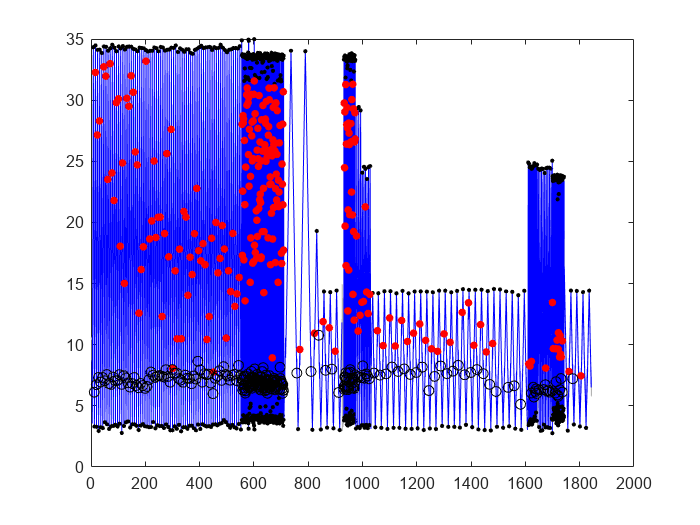

  end